load mystery_song.mat

Defining our struct to hold notes:

- `theVoices.noteNumbers` - **Note number** for each note

- `theVoices.startPulses` - **Starting pulse** for each note

- `theVoices.durations` - **Duration in pulses** for each note

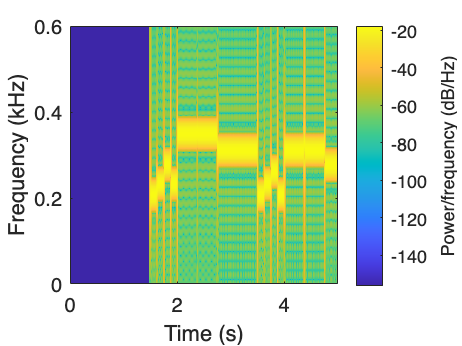

X = 1;
fs = 22050;
beats_per_min = 120;

beats_per_sec = beats_per_min/60;
sec_per_beat = 1/beats_per_sec;
sec_per_pulse = sec_per_beat/4;

tt = 0:(1/fs):250*sec_per_pulse;
xx = zeros(1, length(tt));

for kk = 1:length(theVoices.noteNumbers)
    keynum = theVoices.noteNumbers(kk);
    
    tone = key2note(X, keynum, theVoices.durations(kk)*sec_per_pulse, fs);
    note_indx_start = round((theVoices.startPulses(kk)-1)*sec_per_pulse*fs);
    note_indx_stop = note_indx_start + length(tone) - 1;
    xx(note_indx_start:note_indx_stop) = xx(note_indx_start:note_indx_stop) + tone;
end

soundsc(xx, fs)

spectrogram(xx(1:120000),1024,800,16384,22050,'yaxis')
xlim([0,5])
ylim([0,0.6])